**Statistical Methods**

**Luis Mario Bres Castro**

**Lab 4: Plot Frecuency Modulated Sinusoid Signal **

%Signal Parameters
A=100; 
b=5;
f0=10;
f1=1;

%Time samples
a1=30;
a2=30;
a3=20;
maxFreq=a1+2*a2+3*a3;
samplFreq=5*maxFreq;
samplIntrvl=1/samplFreq;
t=0:samplIntrvl:1;

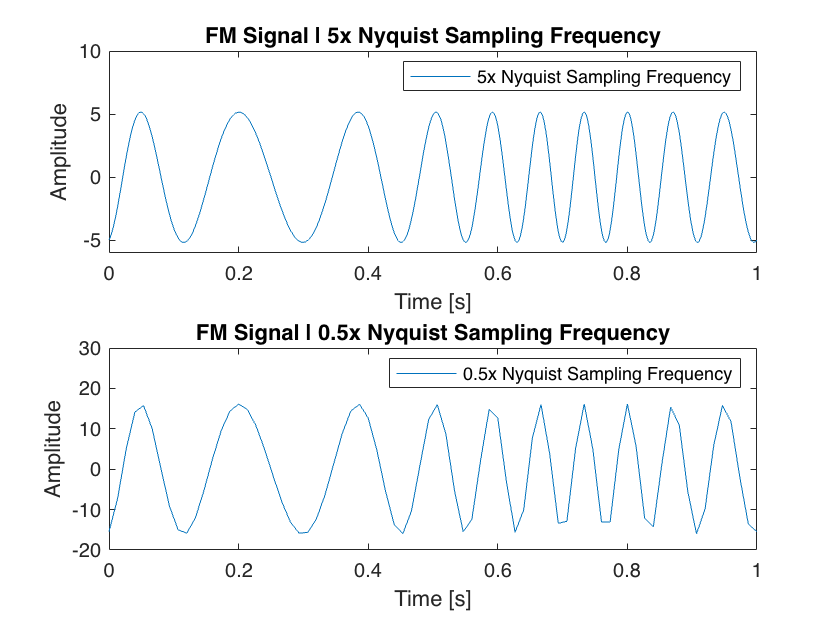

%Generate Signal
SigVec = FMSigGen(t,A,b,f0,f1);

%Plot the signal for 5x Nyquist sampling frequency
subplot(2,1,1)
plot(t,SigVec)
title('FM Signal | 5x Nyquist Sampling Frequency')
legend({'5x Nyquist Sampling Frequency'},'Location','northeast')
xlabel('Time [s]')
ylabel('Amplitude')
ylim([-6 10])

%Time samples and plot of signal for 0.5x Nyquist sampling frequency
subplot(2,1,2)
samplFreq1=0.5*maxFreq;
samplIntrvl1=1/samplFreq1;
t1=0:samplIntrvl1:1;
SigVec1 = FMSigGen(t1,A,b,f0,f1);

plot(t1,SigVec1)
title('FM Signal | 0.5x Nyquist Sampling Frequency')
legend({'0.5x Nyquist Sampling Frequency'},'Location','northeast')
xlabel('Time [s]')
ylabel('Amplitude')
ylim([-20 30])